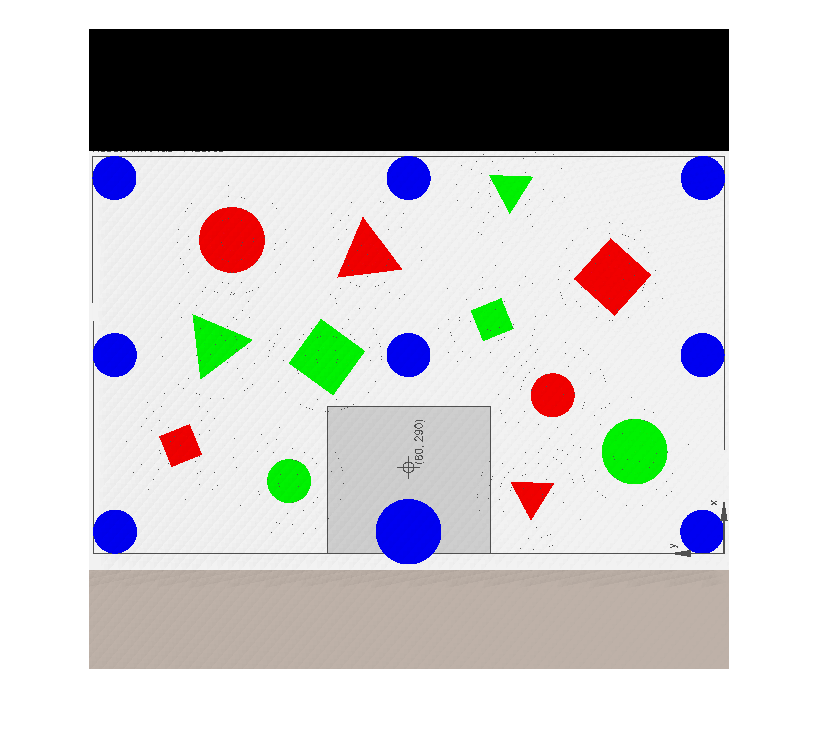

% sim = coppeliaRobot();

q = [0 -24 -21 45 0]; % Perfect for top view picture
% q0 = [0 0 0 0 0];
setJointPositions(sim, q);

% % Capture image
pause(3);
image = getImage(sim);
image(1:122,:,:) = 0;
imshow(image)


data = extractData(image, 1600)  

rowNum = 1

rowNum = 1

data = 2×6 string array
    "red"      "Square"    "319.9255"    "384.2616"    "304076"    "True"
    "green"    "Square"    "320.4003"    "387.1132"    "304069"    "True"


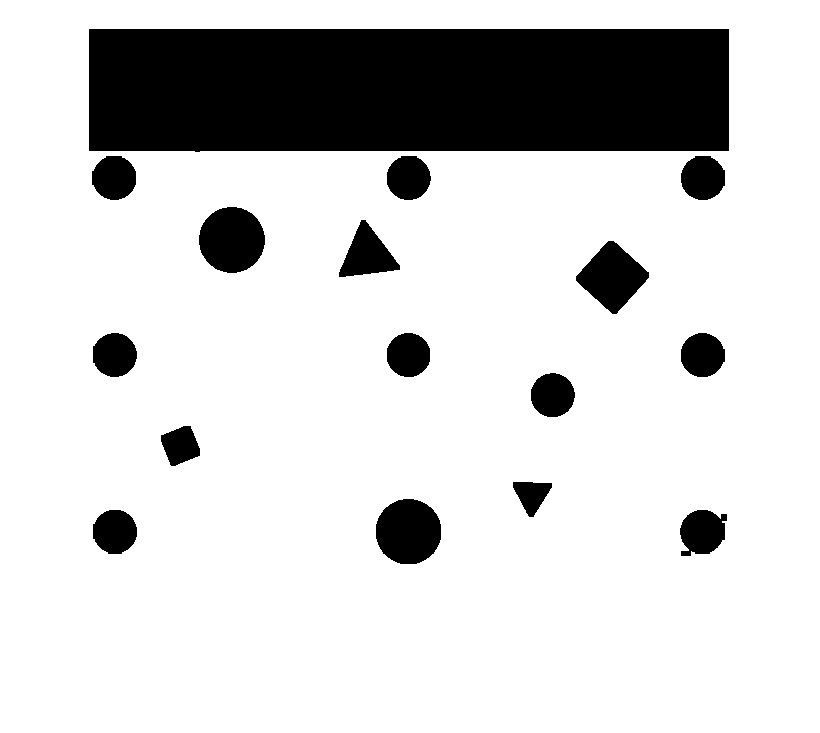


% debugggg

% doubleeeeeeeee
r = image(:,:,1);
g = image(:,:,2);
b = image(:,:,3);

red = imclose(r./(r+g+b) > 0.45, ones(5,5));
blue = imclose(b./(r+g+b) > 0.45, ones(5,5));
green = imclose(g./(r+g+b) > 0.45, ones(5,5));

imshow(green)


% Get Shape props from colour plain
if sum(sum(red))>0
    redProps = regionprops("table",red,"Centroid","Area","Circularity");
else
    redProps = 0;
end
redProps

redProps = 1×3 table
       Area           Centroid        Circularity
    __________    ________________    ___________

    3.0408e+05    319.93    384.26      0.74425  


% % if sum(sum(blue))>0
% %     blueStats = regionprops("table",blue,"Centroid","Area","Circularity");
% % else
% %     blueStats = 0;
% % end
if sum(sum(green))>0
    greenProps = regionprops("table",green,"Centroid","Area","Circularity");
else
    greenProps = 0;
end
greenProps

greenProps = 1×3 table
       Area          Centroid        Circularity
    __________    _______________    ___________

    3.0407e+05    320.4    387.11      0.74423  



init_image = double(imread("init_image2.jpg"));
dest_image = double(imread("init_image3.jpg"));
initData = extractData(init_image, 37260)

rowNum = 2

rowNum = 1

initData = 3×6 string array
    "red"      "Triangle"    "221.9585"    "265.9048"    "38079"    "True" 
    "red"      "Circle"      "808.3106"    "266.0922"    "68322"    "True" 
    "green"    "Triangle"    "515.1408"    "266.0029"    "17175"    "False"


destData = extractData(dest_image, 37260)

rowNum = 1

rowNum = 2

destData = 3×6 string array
    "red"      "Square"      "219.0041"    "260.9999"    "59049"    "True" 
    "green"    "Square"      "509.5238"    "260.4973"    "21591"    "False"
    "green"    "Triangle"    "798.8596"    "253.5989"    "37406"    "True" 
